system model

t = linspace(0, 2*pi, 100);
dt = t(2) - t(1);

% Position equations
x = 2*cos(t); % X position as a function of time
y = sin(2*t); % Y position as a function of time

% vel
dxdt = -2*sin(t); % Rate of change of x with respect to time
dydt = 2*cos(2*t); % Rate of change of y with respect to time

% accel
d2xdt2 = -2*cos(t); % Second derivative of x with respect to time
d2ydt2 = -4*sin(2*t); % Second derivative of y with respect to time

% jerk
d3xdt3 = 2*sin(t); % Third derivative of x with respect to time
d3ydt3 = -8*cos(2*t); % Third derivative of y with respect to time


plot

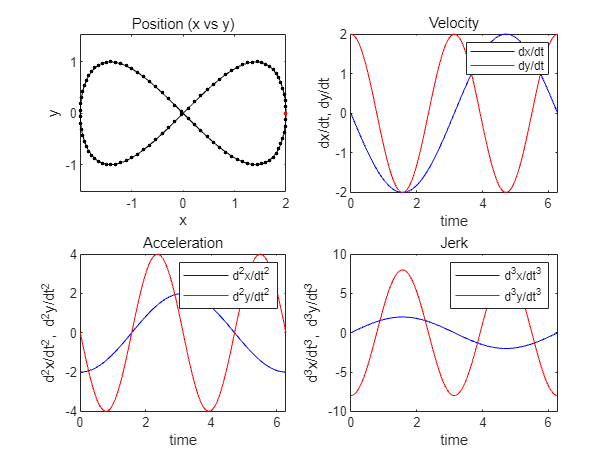

figure;

subplot(2, 2, 1);
plot(x, y, 'k-o','MarkerSize', 2, 'MarkerFaceColor', 'k');hold on;plot(x(1), y(1), 'ro' ,'MarkerSize', 2, 'MarkerFaceColor', 'r');title('Position (x vs y)');
xlabel('x');ylabel('y');axis equal;

subplot(2, 2, 2);
plot(t, dxdt, 'b-', t, dydt, 'r-');title('Velocity');
xlabel('time');ylabel('dx/dt, dy/dt');legend({'dx/dt', 'dy/dt'});

subplot(2, 2, 3);
plot(t, d2xdt2, 'b-', t, d2ydt2, 'r-');title('Acceleration');
xlabel('time');ylabel('d^2x/dt^2, d^2y/dt^2');legend({'d^2x/dt^2', 'd^2y/dt^2'});

subplot(2, 2, 4);
plot(t, d3xdt3, 'b-', t, d3ydt3, 'r-');title('Jerk');
xlabel('time');ylabel('d^3x/dt^3, d^3y/dt^3');legend({'d^3x/dt^3', 'd^3y/dt^3'});

gps, accel sensor 

omega = (dxdt.*d2ydt2 - dydt.*d2xdt2) ./ (dxdt.^2 + dydt.^2); % angular speed (scalar)
speed = sqrt(dxdt.^2 + dydt.^2); % speed (scalar)

% measurement error
gps_sig = 0.1;
omega_sig = 0.3;
speed_sig = 0.1;

% noisy measurements
x_gps = x + gps_sig * randn(size(x));
y_gps = y + gps_sig * randn(size(y));
omega_sens = omega + omega_sig * randn(size(omega));
speed_sens = speed + speed_sig * randn(size(speed));

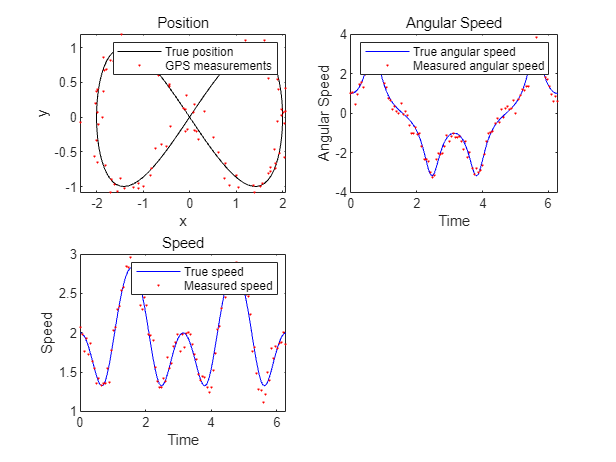

figure;
subplot(2, 2, 1);
plot(x, y, 'k-', x_gps, y_gps, 'ro', 'MarkerSize', 1, 'MarkerFaceColor', 'r');title('Position');
xlabel('x');ylabel('y');legend('True position', 'GPS measurements');

subplot(2, 2, 2);
plot(t, omega, 'b-', t, omega_sens, 'ro', 'MarkerSize', 1, 'MarkerFaceColor', 'r');title('Angular Speed');
xlabel('Time');ylabel('Angular Speed');legend('True angular speed', 'Measured angular speed');

subplot(2, 2, 3);
plot(t, speed, 'b-', t, speed_sens, 'ro', 'MarkerSize', 1, 'MarkerFaceColor', 'r');title('Speed');
xlabel('Time');ylabel('Speed');legend('True speed', 'Measured speed');

kalman

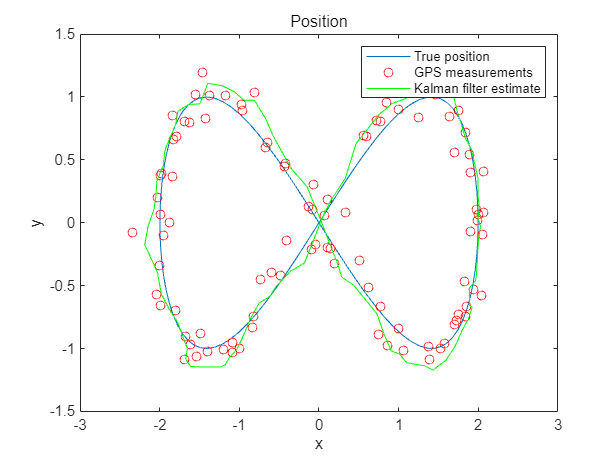

% Kalman Filter matrices
A = [1 dt dt^2/2 0 0 0;
     0 1 dt 0 0 0;
     0 0 1 0 0 0;
     0 0 0 1 dt dt^2/2;
     0 0 0 0 1 dt;
     0 0 0 0 0 1];

Q1 = [dt^3/6; dt^2/2; dt; 0; 0; 0];
Q2 = [0; 0; 0; dt^3/6; dt^2/2; dt];
j_var = max(var(d3xdt3), var(d3ydt3));
Q = j_var * (Q1 * Q1' + Q2 * Q2');

H = [1 0 0 0 0 0;
     0 0 0 1 0 0];

R = diag([gps_sig^2, gps_sig^2]);

x_init = [x(1) dxdt(1) d2xdt2(1) y(1) dydt(1) d2ydt2(1)];
P_init = 0.01 * eye(length(x_init));

% Create an observation vector of noisy GPS signals
observations = [x_gps; y_gps]';

% Matrix dimensions
nx = size(Q, 1);
ny = size(R, 1);
nt = size(observations, 1);

% Allocate identity matrix for re-use
Inx = eye(nx);

% Allocate result matrices
x_pred = zeros(nt, nx);
P_pred = zeros(nx, nx, nt);
x_est = zeros(nt, nx);
P_est = zeros(nx, nx, nt);
K = zeros(nx, ny, nt);

% Set initial prediction
x_pred(1, :) = x_init;
P_pred(:, :, 1) = P_init;

% For each time step
for i = 1:nt

    % Prediction stage
    if i > 1
        x_pred(i, :) = A * x_est(i-1, :)';
        P_pred(:, :, i) = A * P_est(:, :, i-1) * A' + Q;
    end

    % Estimation stage
    y_obs = observations(i, :)';
    K(:, :, i) = P_pred(:, :, i) * H' / (H * P_pred(:, :, i) * H' + R);
    x_est(i, :) = x_pred(i, :) + (K(:, :, i) * (y_obs - H * x_pred(i, :)'))';
    P_est(:, :, i) = (Inx - K(:, :, i) * H) * P_pred(:, :, i);
end

% Plotting the position
figure;
plot(x, y, 'DisplayName', 'True position');
hold on;
scatter(x_gps, y_gps, 'r', 'DisplayName', 'GPS measurements');
plot(x_est(:, 1), x_est(:, 4), 'g', 'DisplayName', 'Kalman filter estimate');
xlabel('x');
ylabel('y');
title('Position');
legend show;